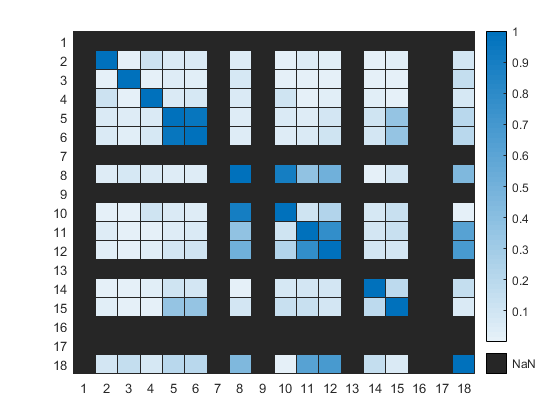

clear all
rng(1);
% load simdata
AA = readmatrix('C:\Users\Ridvanz\Desktop\KNMI_long.txt');

AA= AA(280000:end,:);
corz = corr(AA);
heatmap(abs(corz));

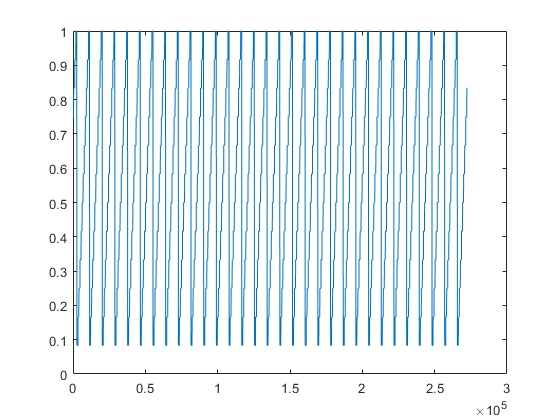


% +0.001*randn(size(qm))

tempoz=num2str(AA(:,2));
months=str2num(tempoz(:,5:6))/12;
plot(months);

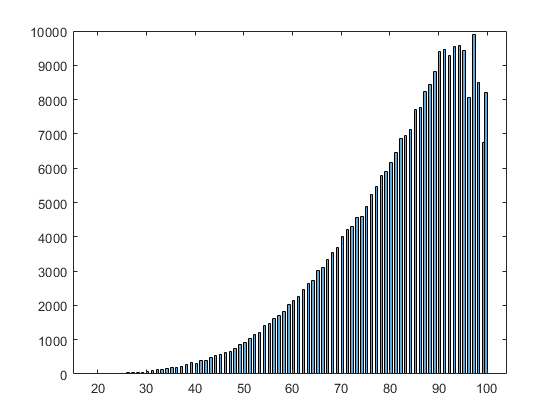


hourz= AA(:,3)/24;

histogram(AA(:,end));

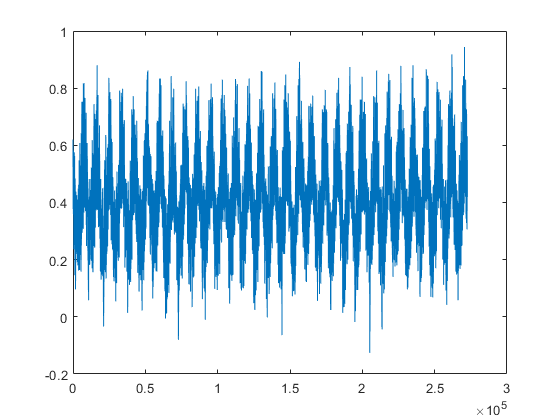


plot((AA(:,8)+100)/500);


u11=AA(:,end)/100;
u22=(AA(:,8)+100)/500;

yz=AA(:,12)/350;


m = 1;
trainsize = 250000;
ahead =24

ahead = 24


u8 = u22(1:1+trainsize);
u7 = u22((m*1):((m*1)+trainsize));
u6 = u22((m*2):((m*2)+trainsize));
u5 = u22((m*3):((m*3)+trainsize));
u4 = u11(1:1+trainsize);
u3 = u11((m*1):((m*1)+trainsize));
u2 = u11((m*2):((m*2)+trainsize));
u1 = u11((m*3):((m*3)+trainsize));
y1 = yz((m*3):((m*3)+trainsize));
y2 = yz((m*2):((m*2)+trainsize));
y3 = yz((m*1):((m*1)+trainsize));
y4 = yz(1:1+trainsize);
hourzu = hourz((m*3):((m*3)+trainsize));
monthsu = months((m*3):((m*3)+trainsize));

featurez= [u8 u7 u6 u5 u4 u3 u2 u1 hourzu monthsu y1 y2 y3 y4];
min(featurez)

ans =    -0.1260   -0.1260   -0.1260   -0.1260    0.2100    0.2100    0.2100    0.2100    0.0417    0.0833         0         0         0         0


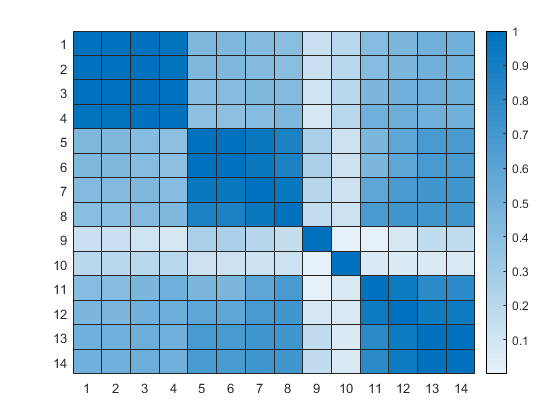

ans =   HeatmapChart with properties:

        XData: {14×1 cell}
        YData: {14×1 cell}
    ColorData: [14×14 double]

  Show all properties


zeta = yz((m*3+ahead):((m*3+ahead)+trainsize));

u8t = u22(trainsize+10000+1:end-4*m+1-ahead);
u7t = u22((trainsize+10000+1*m):(end-3*m-ahead));
u6t = u22((trainsize+10000+2*m):(end-2*m-ahead));
u5t = u22((trainsize+10000+3*m):(end-1*m-ahead));
u4t = u11(trainsize+10000+1:end-4*m+1-ahead);
u3t = u11((trainsize+10000+1*m):(end-3*m-ahead));
u2t = u11((trainsize+10000+2*m):(end-2*m-ahead));
u1t = u11((trainsize+10000+3*m):(end-1*m-ahead));
y1t = yz((trainsize+10000+3*m):(end-1*m-ahead));
y2t = yz((trainsize+10000+2*m):(end-2*m-ahead));
y3t = yz((trainsize+10000+1*m):(end-3*m-ahead));
y4t = yz(trainsize+10000+1:end-4*m+1-ahead);
hourzut = hourz((trainsize+10000+3*m):(end-1*m-ahead));
monthsut = months((trainsize+10000+3*m):(end-1*m-ahead));

tfeaturez= [u8t u7t u6t u5t u4t u3t u2t u1t hourzut monthsut y1t y2t y3t y4t];

tlabels = yz((trainsize+10000+m*3+ahead):(end-m));
refer = yz((trainsize+10000+m*3+ahead):(end-m));

heatmap(abs(corr(featurez)))


featurez(featurez<0)= 0;

% plot(featurez)
% plot(tfeaturez)

[N, d]=size(featurez); 

nn = 2;  %degree B-spline
knotintervals = 4;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;
indexes(indexes<1)= 1;

min(indexes)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1


max(indexes)

ans =      4     4     4     4     4     4     4     4     4     4     4     4     4     4



inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 7.8364e+10

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=6;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;   r(d+1)=1;
r(2)=nnn;  r(d)=nnn;
r(2)=R-1;  r(d)=R-1;

disp(r)

     1     5     6     6     6     6     6     6     6     6     6     6     6     5     1



n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2

difforder = 2

P = diff(eye(nnn),difforder);
PP = P'*P;

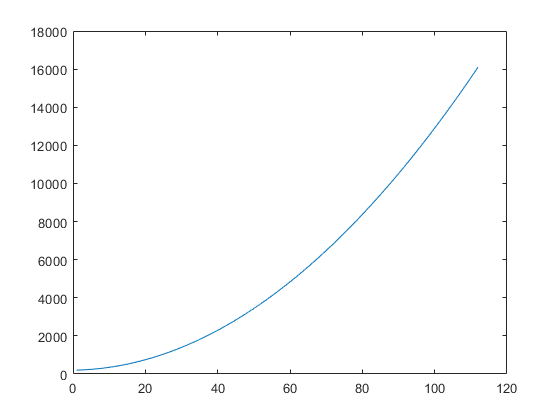

res1=[];
res2=[];
MAXITR = 8*d;

for j = 1:MAXITR
nselect(j) = 200+floor(((j+1)/(MAXITR*4))^2*(N));
% nselect(j) = 100;

gamma(j)=0.001*(nselect(j)/N)^2;
end
plot(nselect)

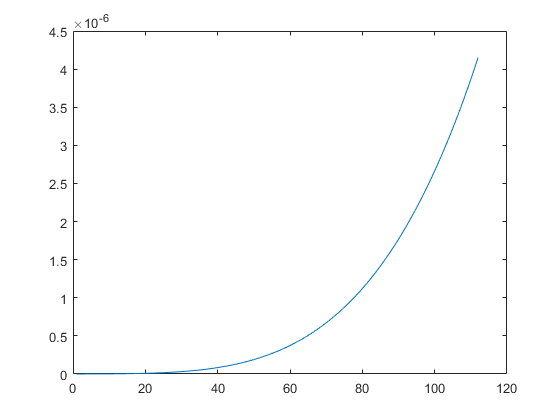

plot(gamma)

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated


 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            

dataselect = randperm((N),nselect(itr));
% dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%        
                   
%         -------------------difference penalty 
        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));         

        g=pinv(A'*A + gamma(itr)*WWW)*(A'*zeta(dataselect,:));

        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect(j)); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end

                if (res1(itr)<10*eps) || (abs(res2(itr)-res2(itr-2))<0.0001)
                 disp(res1(itr))
                 break;
                 end
            end
            
            disp(["iteration:" itr timer res1(itr) res2(itr)])
            itr=itr+1; %update iteration
            
        end   

        
end  

    "iteration:"    "1"    "0.7673"    "0.0016936"    "32304925.3189"

    "iteration:"    "2"    "1.4506"    "0.010083"    "45511111.3683"

    "iteration:"    "3"    "2.1892"    "0.0041277"    "9069453.438"

    "iteration:"    "4"    "2.8644"    "0.0070192"    "12056950.9733"

    "iteration:"    "5"    "3.5556"    "0.0059206"    "7737587.4437"

    "iteration:"    "6"    "4.2662"    "0.010885"    "12253808.8344"

    "iteration:"    "7"    "4.9518"    "0.0074733"    "10190315.0177"

    "iteration:"    "8"    "5.6581"    "0.011"    "10575852.8094"

    "iteration:"    "9"    "6.3476"    "0.011611"    "12486974.4224"

    "iteration:"    "10"    "7.0303"    "0.010785"    "8199899.8288"

    "iteration:"    "11"    "7.7174"    "0.0067474"    "8208065.9615"

    "iteration:"    "12"    "8.3931"    "0.010564"    "4901371.5724"

    "iteration:"    "13"    "9.1112"    "0.0093521"    "6680758.7206"

    "iteration:"    "14"    "9.7853"    "0.012192"    "4215468.5565"

    "iteration:"   

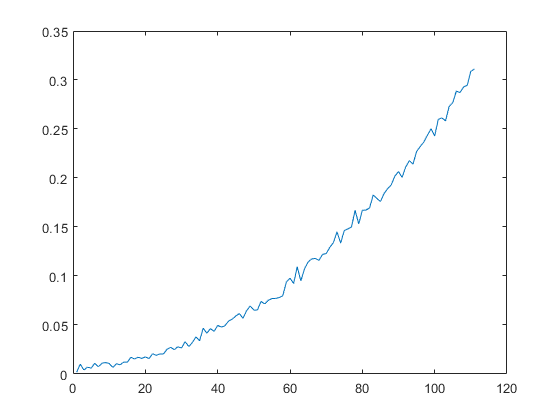

plot(res1)

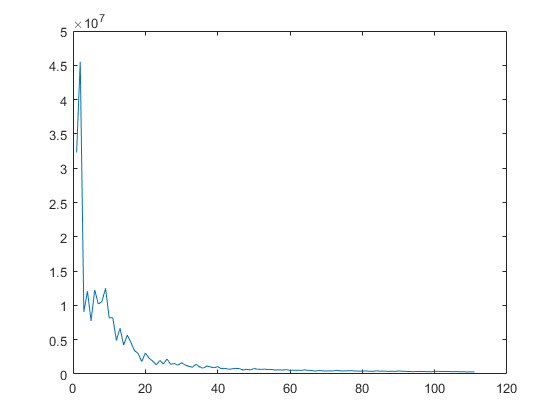

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;
indexes(indexes<1)= 1;


min(indexes)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1


max(inputs)

ans =     0.9920    0.9920    0.9920    0.9920    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



inputs = (tfeaturez/knotdist)-indexes+1;

min(inputs)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


max(inputs)

ans =     0.9920    0.9920    0.9920    0.9920    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9943    0.9943    0.9943    0.9943


for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,1);

for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end



% [tlabelz, id] = sort(tlabels);
tlabelz = tlabels;
outputsrt = output;


testset = 6000:6500

testset =         6000        6001        6002        6003        6004        6005        6006        6007        6008        6009        6010        6011        6012        6013        6014        6015        6016        6017        6018        6019        6020        6021        6022        6023        6024        6025        6026        6027        6028        6029        6030        6031        6032        6033        6034        6035        6036        6037        6038        6039        6040        6041        6042        6043        6044        6045        6046        6047        6048        6049


testset = 300:400

testset =    300   301   302   303   304   305   306   307   308   309   310   311   312   313   314   315   316   317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346   347   348   349


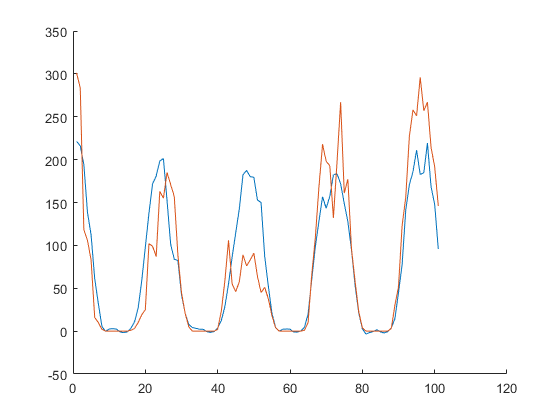


figure
hold on
plot(outputsrt(testset)*350)
% plot(tlabelz)
plot(refer(testset)*350)

hold off

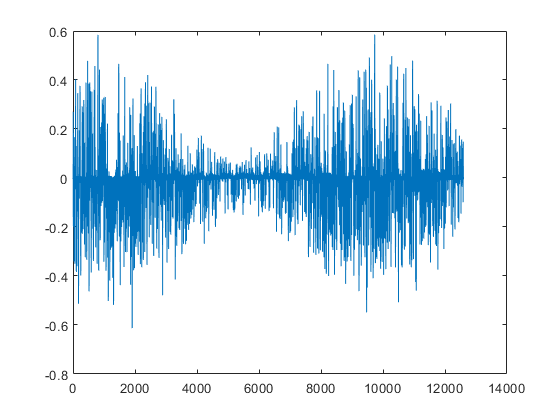

erboi = (outputsrt-refer);
plot(erboi)

pererror = sum(abs(erboi))/Nt

pererror = 0.0591

relerror = sum(abs(erboi)/sum(abs(refer)))

relerror = 0.3865

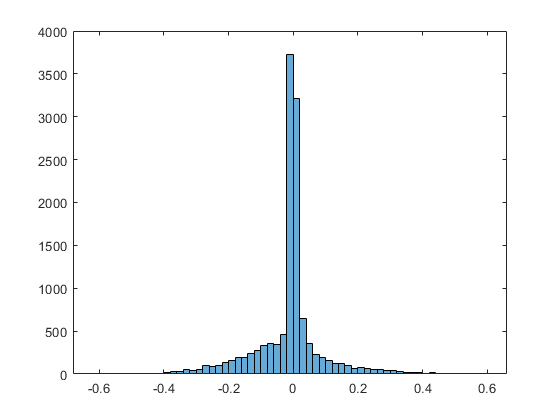

ans = 36.9158

ans = 1000

histogram((erboi)')

sqrt(sum((350*erboi).^2)/Nt)




% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end

% 
% difforder=2
% P = diff(eye(nnn),difforder)
% PP = P'*P
% 
% sweepindex=4
% tic
% for j=1:d
% Csize = TN.n(j,:);
% 
% Dm = reshape(permute(G{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
% mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% PD = P*Dm;
% DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
% eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
% end
% eyez{d+1}=1;
% 
% for p= 1:d
%     Dsize = TN.n(sweepindex,:);   
%         if sweepindex==p
%             D1 = eyez{sweepindex};
%             D2 = PP(:);
%             D3 = eyez{sweepindex+1};
% 
%         elseif sweepindex<p
%             D1 = eyez{sweepindex};  
%             D2 = eyep{sweepindex};   
%             D3= DWD{p}*eyez{p+1};           
%             for it=(p-1):-1:(sweepindex+1)               
%                 D3 = DD{it}*D3;
%             end                        
%          
%         elseif sweepindex>p   
%             D1= eyez{p}'*DWD{p};
%             for it=(p+1):(sweepindex-1)               
%                 D1 = D1*DD{it};
%             end
%             D1=D1';
%             D2 = eyep{sweepindex};   
%             D3= eyez{sweepindex+1}; 
% 
%         end
%     
%     WW = kron(D3, kron(D2, D1));
%     Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
%     W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]);
%     
% end
% 
% WWW = W{1};
% for s =2:d
%     WWW = WWW + W{s};
% end
% 
% imagesc(WWW)
% % imagesc(W{d})
% toc
% 
% 
% % 
% % 
% % W =  permute(reshape(WW, c1 c1 c2 c2 c3 c3), [1 3 5 2 4 6]
% % reshape(W, [c1*c2*c3 c4*c5*c6])

% 
% new = kron([2 2 2]',[1 2 3]')
% lef = [1 2 3]
% mid =[1 2 3; 4 5 6; 7 8 9]
% right =[2 2 2]'
% lef*mid *right
% 
% new(:)'*mid(:)
% 